## **Problem 3**

**Redo the “Mock 1D NaCl” problem that we did in class. A 1D chain consists of alternating Na and Cl atoms, with the spacing between Na and Cl them being *****a*****. If Na contributes its s orbital (energy *****E*****s) and Cl contributes its px orbital (energy *****E*****p) to the formation of this fictitious crystal, with the magnitude of the overlap integral denoted as *****E*****sp, answer the following:**

**a) What is the lattice period?**

The lattice period is the smallest region that can be used for symmetry for the entire crystal, so it ends when we start at an Na atom and ends at an Na atom (or with a Cl atom). Since the spacing between each alternating atom is a, it takes 2a to reach an Na atom from the start.


$$\textrm{period}=2a$$


**b) How many atoms are in the basis?**

Just like in class, there are two atoms in the basis. One chlorine and one sodium atom.

**c) How many bands will form**

Each orbital forms a band, and since there are two atoms, each contributing one orbital, two bands will form.

**d) Calculate and graph the energy dispersions for all the bands across the Brillouin zone.**

The nearest neighbors for any atom are both at distance *a *apart. We start with solving the determinant for 


$$det   \pmatrix{E_s -E & E_{sp}(e^{ika} + e^{-ika}) \cr E_{sp}(e^{ika} + e^{-ika}) & E_{p_x}-E} = 0$$


and using Euler's formula, the matrix can be rewitten as;


$$det   \pmatrix{E_s -E & 2E_{sp}cos(ka) \cr 2E_{sp}cos(ka) & E_{p_x}-E} = 0$$


solving for the values of $E_k$ gives us the equation


$$E_s  E_{p_x} - E(E_s + E_{p_x}) +E^2 - 4E_{sp}^2cos^2(ka) = 0$$


but we can then set it up in the quadratic formula;


$$E^2 - E(E_s + E_{p_x}) + (E_sE_{p_x} - 4E_{sp}^2cos^s(ka)) = 0$$



$$E(k) = \frac{E_s + E_{p_x} \pm \sqrt{(E_s+E_{p_x})^2 - 4(E_sE_{p_x}-  4E_{sp}^2 cos^2(ka))} } {2}$$


Since the s-orbital, px-orbital, and overlap energies are all constant throughout the entire crystal, the energy only depends on the cosine term.


$$E(k) \propto\pm  \sqrt{cos^2(k)} \propto \pm cos(k), \frac{-\pi}{2a}< k < \frac{+\pi}{2a}$$


To properly graph this, I'll set the energies to simple integers

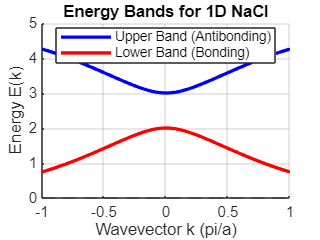

clc
clear
close all

Es = 2;
Epx = 3; % this orbital is higher in energy
Esp = 1;

k = linspace(-pi/2, pi/2, 100);

% This is an even more simplified eqaution than above
E_plus = (Es + Epx) / 2 + sqrt(((Es - Epx)/2)^2 + 4 * Esp^2 * sin(k).^2);
E_minus = (Es + Epx) / 2 - sqrt(((Es - Epx)/2)^2 + 4 * Esp^2 * sin(k).^2);

hold on;
grid on;
plot(k, E_plus, 'b', 'LineWidth', 2); % Upper band
plot(k, E_minus, 'r', 'LineWidth', 2); % Lower band

xlabel('Wavevector k (pi/a)');
ylabel('Energy E(k)');
title('Energy Bands for 1D NaCl');
xlim([-1 1])
yline(0, '--k');  % Reference energy line
xline(-pi/2, '--k');  % Brillouin Zone boundary
xline(pi/2, '--k');   % Brillouin Zone boundary

% Adding the legend
legend('Upper Band (Antibonding)', 'Lower Band (Bonding)', 'Location', 'Best');
hold off;